# Explicit integration of Von Mises plasticity with linear hardening

clear all
clc

## Material Properties

#### Elastic Properties

E = 70000; %Young's Modulus in MPa
nu = 0.33; %Poisson's Ratio

#### Plastic properties

sigma_y0 = 150; % Initial yield strength in MPa
h = 300; % Hardening modulus

## Initial values of stress and strain vectors

sigma_0 = [0 0 0 0 0 0]';
epsilon_0 = [0 0 0 0 0 0]';

## Elastic Matrix

lambda = nu*E/((1+nu)*(1-2*nu)); % Lame constant 1
G = E/(2*(1+nu)); %Lame constant 2 - Shear Modulus in MPa
C = [lambda+2*G lambda lambda 0 0 0;
     lambda lambda+2*G lambda 0 0 0;
     lambda lambda lambda+2*G 0 0 0;
     0 0 0 G 0 0;
     0 0 0 0 G 0;
     0 0 0 0 0 G];

##  Input for strain increment

%Input for strain increment
de11 = 0.182322;
de22 = -0.090664;
de33 = -0.090664;
% de11 = 0.095315;
% de22 = 0.095315;
% de33 = -0.188619;
de12 = 0;
de13 = 0;
de23 = 0;

#### Total strain applied over a number of increments

n = 10000;
%Strain increment per step
depsilon = [de11/n de22/n de33/n de12/n de13/n de23/n]';

## Initialise the variables to their initial value

sigma = sigma_0; 
epsilon = epsilon_0;
eqpl = 0;

## Begin the increments

for i = 1:n

#### **Evaluate current Von Mises equivalent stress and yield stress**

smises = sqrt(0.5*((sigma(1)-sigma(2))^2 + (sigma(2)-sigma(3))^2 + (sigma(3)-sigma(1))^2 + 6*(sigma(4)^2 + sigma(5)^2 + sigma(6)^2)));
sigma_y = sigma_y0 + h*eqpl;

#### **Check for yield**

yieldfn = smises - sigma_y;
if yieldfn<0

**Elastic deformation**

    deqpl = 0;
    dsigma = C*depsilon;
else

#### Plastic deformation

Evaluate flow vector using flow rule

shydro = (sigma(1) + sigma(2)+ sigma(3))/3;
    B(1) = 3*(sigma(1) - shydro)/2;
    B(2) = 3*(sigma(2) - shydro)/2;
    B(3) = 3*(sigma(3) - shydro)/2;
    B(4) =  3*sigma(4);
    B(5) =  3*sigma(5);
    B(6) =  3*sigma(6);
    N = B'/smises;

Calculate the increment in plastic multiplier

deqpl = (N'*(C*depsilon))/((N'*(C*N)) + h);

Calculate the increments in plastic strain and stress

    depsilon_p = deqpl*N;
    dsigma = C*(depsilon - depsilon_p);
end

#### Update the stresses and strains

    sigma = sigma + dsigma;
    epsilon = epsilon + depsilon;
    smises = sqrt(0.5*((sigma(1)-sigma(2))^2 + (sigma(2)-sigma(3))^2 + (sigma(3)-sigma(1))^2 + 6*(sigma(4)^2 + sigma(5)^2 + sigma(6)^2)));
    eqpl = eqpl + deqpl;
    a1(i,:) = epsilon;
    a2(i,:) = sigma;
    a3(i) = eqpl;
    a4(i) = smises;
end
strain_x = a1(:,1);
stress_x = a2(:,1);

#### Plot graphs

strain_x vs stress_x

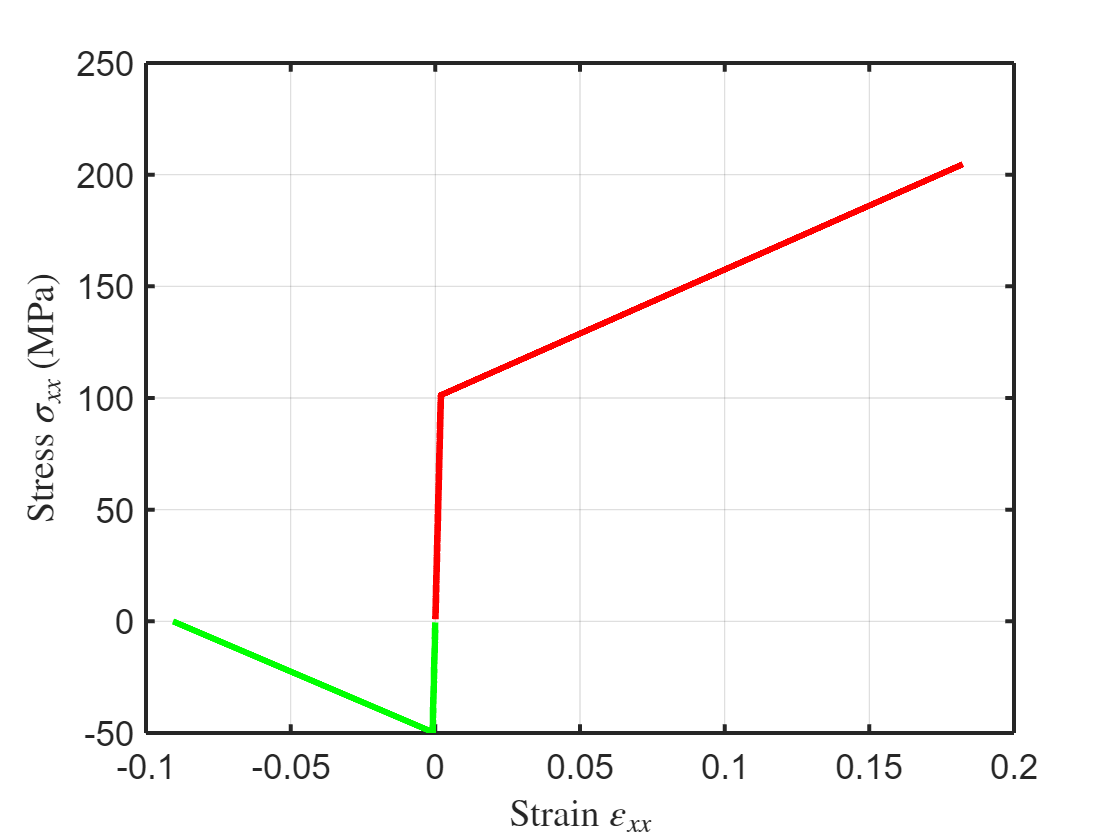

figure(1)
plot(strain_x, stress_x,'LineWidth',2.5,'Color',[1 0 0])
xlabel('Strain $\varepsilon_{xx}$','FontSize',20,'FontWeight','normal', 'Interpreter','latex');
ylabel('Stress $\sigma_{xx}$ (MPa)','FontSize',20,'FontWeight','normal', 'Interpreter','latex');
box on
grid on
ax = gca;
ax.LineWidth = 1.5;
ax.GridLineWidth = 0.5;
ax.FontSize = 13;

eqpl vs smises

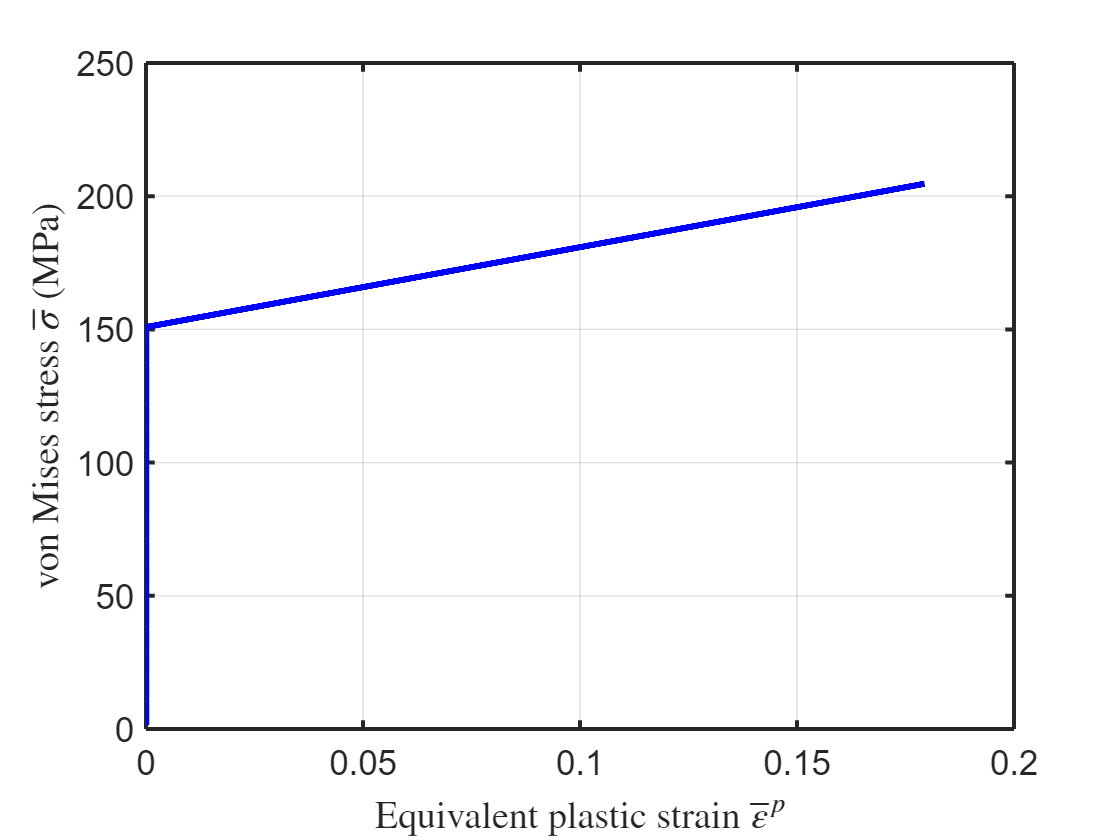

figure(2)
plot(a3, a4,'LineWidth',2.5,'Color',[0 0 1])
xlabel('Equivalent plastic strain $\overline{\varepsilon}^p$','FontSize',20,'FontWeight','normal', 'Interpreter','latex');
ylabel('von Mises stress $\overline{\sigma}$ (MPa)','FontSize',20,'FontWeight','normal', 'Interpreter','latex');
box on
grid on
ax = gca;
ax.LineWidth = 1.5;
ax.GridLineWidth = 0.5;
ax.FontSize = 13;